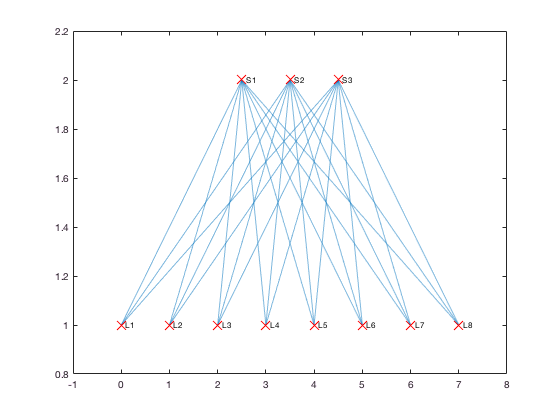

addpath('kShortestPath');
addpath('graphTopology');
tic;
G=graphTopology(false,false,'SpineLeaf',3,8,2);
p=plotGraphtopology(G);

toc

Elapsed time is 0.296869 seconds.


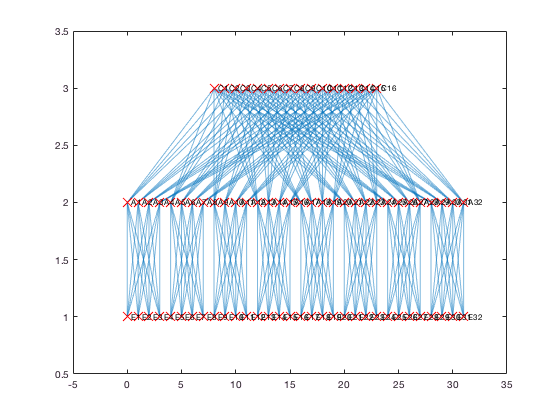

tic;
G=graphTopology(false,false,'Portland',8);
p=plotGraphtopology(G);

toc

Elapsed time is 0.568274 seconds.


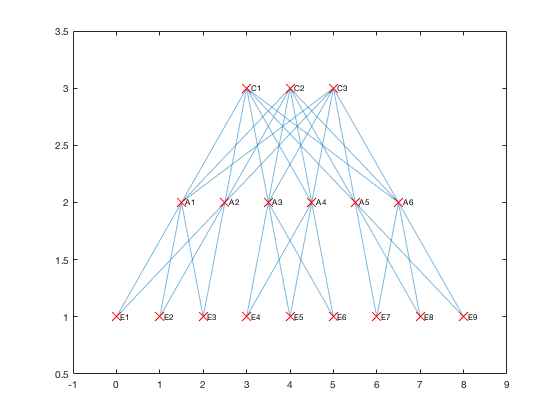

tic;
G=graphTopology(false,false,'VL2',6);
p=plotGraphtopology(G);

toc

Elapsed time is 0.345124 seconds.


netCostMatrix=full(adjacency(G));

TestKShortestPath(1);

You selected case #1, a 4x4 network:
   Inf     1   Inf     1
     1   Inf     1     1
   Inf     1   Inf   Inf
   Inf   Inf   Inf   Inf

The path request is from source node 3 to destination node 4, with K = 5 

Result of Function call: kShortestPath(netCostMatrix, source, destination, k)  = 

Path # 1:
     3     2     4

Cost of path 1 is  2.00

Path # 2:
     3     2     1     4

Cost of path 2 is  3.00



[paths, cost]=kshortestpathsx(G,[1 2],3,'unweight');
disp(paths{1,1}{1,1})

     1     4     2



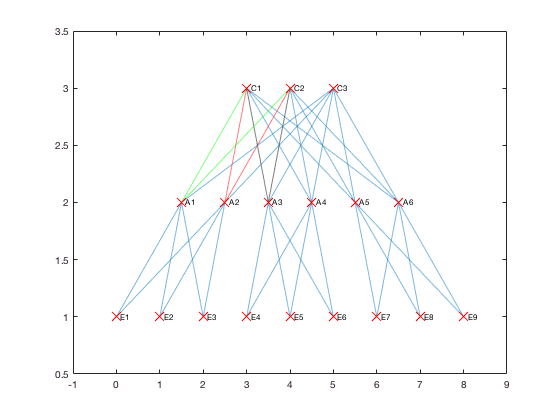

highlight(p,paths{1,1}{1,1},'EdgeColor','g')
highlight(p,paths{1,1}{1,2},'EdgeColor','r')
highlight(p,paths{1,1}{1,3},'EdgeColor','k')